# Actividad 3 (evaluacion)

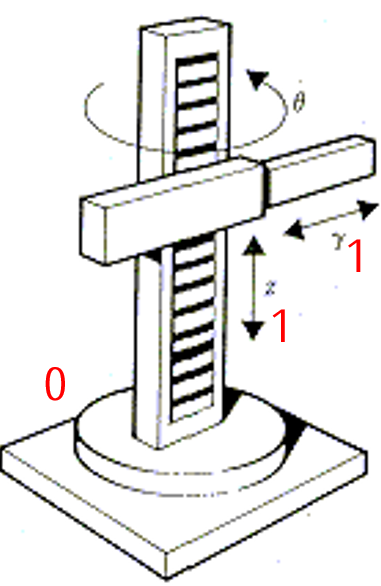

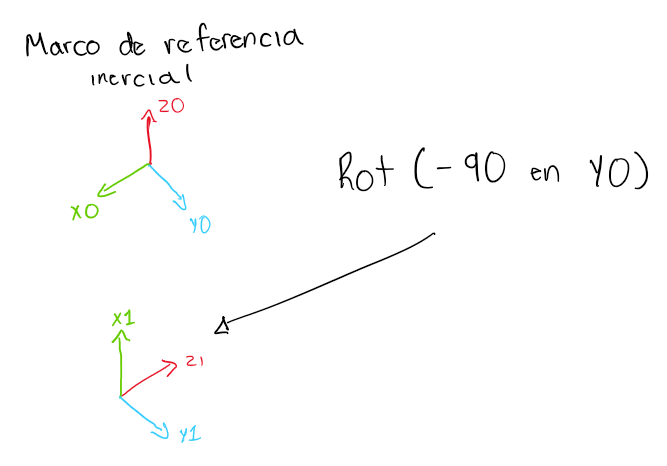

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) l2(t) l3(t) t l1

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 

%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

%Posición de la articulación 2 respecto a 0
P(:,:,2)= [0; 0; l2];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,2)= [0  0 -1;
           0  1  0;
           1  0  0];

%Posición de la articulación 3 respecto a 0
P(:,:,3)= [0; 0; l3];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    %disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    %pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/  _________                     ________              \
|   d                             d                    |
|  -- th1(t) sin(th1(t)) l3(t) - -- l3(t) cos(th1(t))  |
|  dt                            dt                    |
|                                                      |
|   ________               _________                   |
|    d                      d                          |
| - -- l3(t) sin(th1(t)) - -- th1(t) cos(th1(t)) l3(t) |
|   dt                     dt                          |
|                                                      |
|                       ________                       |
|                        d                             |
|                       -- l2(t)                       |
\                       dt                             /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Este robot es de tres grados de libertad, una junta es rotacional y las otras dos lineales.

Se realizaron traslaciones y rotaciones, de acuerdo a la imagen inicial, estas transformaciones se realizaron de tal forma que al rotar, la traslacion siempre fuera en Z, pero en la velocidad lineal en los tres ejes estan las traslaciones (l2 y l3) aunque se realizaron en el eje Z, esto es debido al marco de referencia inercial y a que hay dos juntas prismaticas

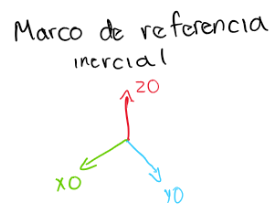

La traslacion en l2 se realizo en Z y si sale en la velocidad lineal, la traslacion l3 se encuentra en el eje X del marco de referencia inercial, por eso sale en X en la velocidad lineal y sale en Y por los senos y cosenos de la junta rotacional que en la matriz de posicion se pusieron en el eje X y Y.

En cuanto a la junta rotacional los valores en X y Y son 0, debido a que segun el marco de referencia inercial el giro es en Z y no hay mas juntas rotacionales, por eso solo hay en Z velocidad angular. 